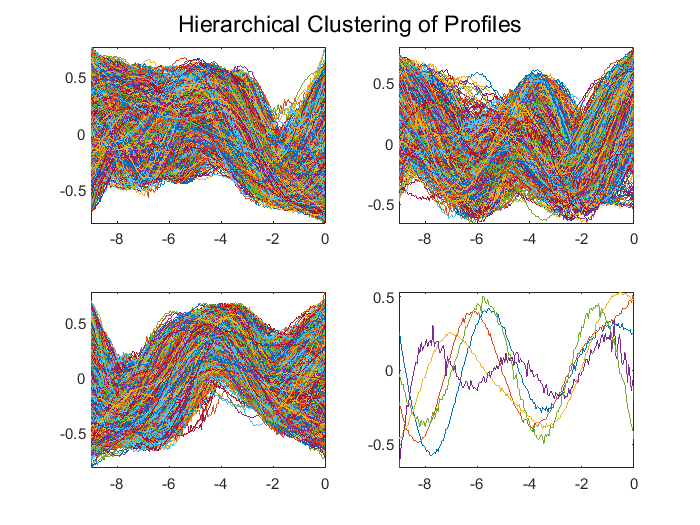

all_spike_triggers = all_spike_triggers - mean(all_spike_triggers,2);
range = max(all_spike_triggers,[],2) - min(all_spike_triggers, [], 2);
patterns = all_spike_triggers./range;
nanIndices = any(isnan(patterns),2);
patterns(nanIndices,:) = [];
% patterns = patterns(1:500,:);

corrDist = pdist(patterns,'corr');
clusterTree = linkage(corrDist,'average');

clusters = cluster(clusterTree,'maxclust',4);
 

figure
for c = 1:4
    subplot(2,2,c);
    plot(t,patterns((clusters == c),:)');
    axis tight
end
sgtitle('Hierarchical Clustering of Profiles');

## k-means clustering

[cidx, ctrs] = kmeans(patterns,16,'dist','corr','rep',5,'disp','final');

Replicate 1, 1 iterations, total sum of distances = 0.785225.
Replicate 2, 2 iterations, total sum of distances = 1.2218.
Replicate 3, 1 iterations, total sum of distances = 0.640979.
Replicate 4, 1 iterations, total sum of distances = 0.693649.
Replicate 5, 4 iterations, total sum of distances = 0.69511.
Best total sum of distances = 0.640979


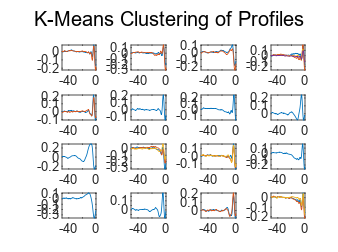

figure;
for c = 1:16
    subplot(4,4,c);
    plot(t,patterns((cidx == c),:)');
    axis tight
end
sgtitle('K-Means Clustering of Profiles');

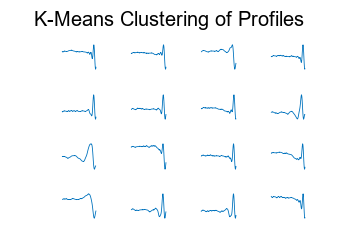


figure
for c = 1:16
    subplot(4,4,c);
    plot(t,ctrs(c,:)');
    axis tight
    axis off
end
sgtitle('K-Means Clustering of Profiles');

## PCA

[pc, zscores, pcvars] = pca(patterns);

pcvars./sum(pcvars) * 100

ans =    50.2308
   25.3324
   12.0972
    6.4783
    4.1227
    1.3536
    0.2299
    0.0313
    0.0030
    0.0020


cumsum(pcvars./sum(pcvars) * 100)

ans =    50.2308
   75.5633
   87.6605
   94.1388
   98.2615
   99.6150
   99.8449
   99.8762
   99.8792
   99.8812


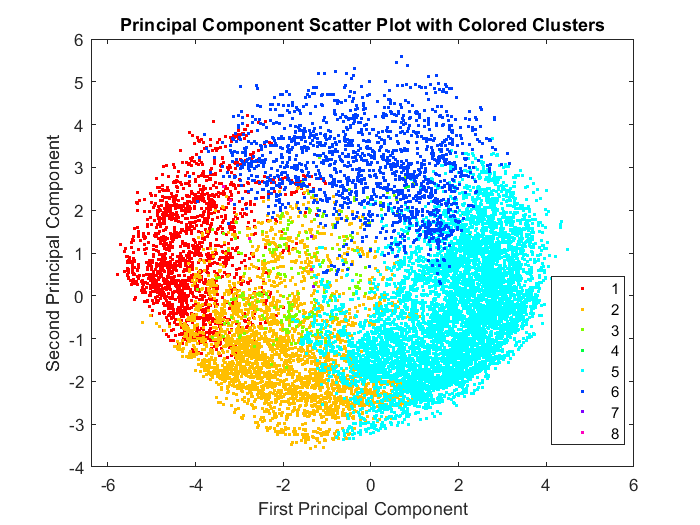


figure
pcclusters = clusterdata(zscores(:,1:22),'maxclust',8,'linkage','av');
gscatter(zscores(:,1),zscores(:,2),pcclusters,hsv(8))
xlabel('First Principal Component');
ylabel('Second Principal Component');
title('Principal Component Scatter Plot with Colored Clusters');